# This function generates random process with gamma distribution and exponential autocorelation function.

This function generates random process with gamma distribution, $x(t)\sim\Gamma(a,b)$, with PDF $f(x|a,b)=\frac{x^{a-1}}{b^a\Gamma(a)}\exp\left(-\frac{x}{b}\right)$ and normalized autocorelation function $C_x(\tau) = \exp\left(-\frac{\tau}{\tau_c}\right)$ with autocorrelation time $\tau_c$.

### Syntax

- `a,b` : distribution parameters

- `dt` : sampling time, $\Delta t$ [sec]

- `tau_c` : autocorrelation time, $\tau_c$ [sec]

- `N` : number of samples, $N$

- `x0` (optional): initial value, $x(0)=x_0$ (default is $E[x(t)]=ab$)

- `L` (optional): dimensionality of the resulting process, $L$, such that $\mathbf{x}(t) = \left[x_1(t)\ldots x_L(t)\right]^T$ (default is $L=1$). In this case initial values have to be  L-dimensitional, $\mathbf{x}(0) = \left[{x_0}_1\ldots {x_0}_L]^T$.

### Application note

For numerical accuracy reasons, **it is recommended that **$\tau_c\gg \Delta t$** (at least factor 10)**. Otherwise, the resulting distribution may be inaccurate! 

## Examples

### Example 1

Generate process with given parameters

A portion of the the process

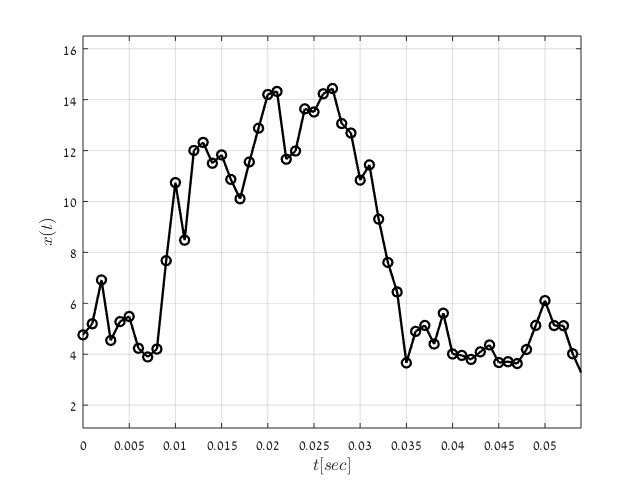

Comparison between theoretical PDF and the histogram of the process.

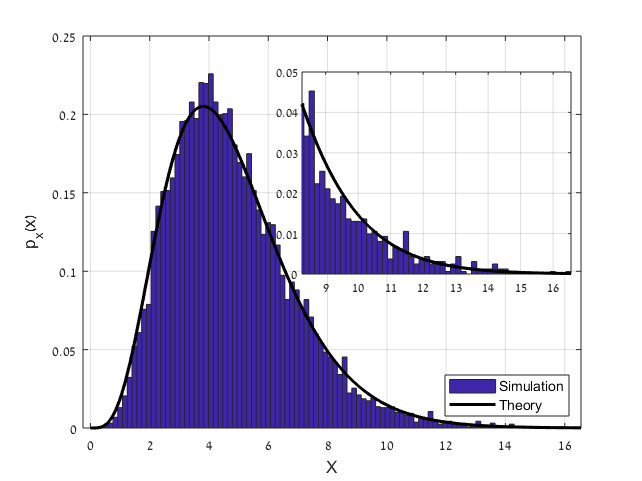

Comparison between theoretical autocorrelation and the numerical result.

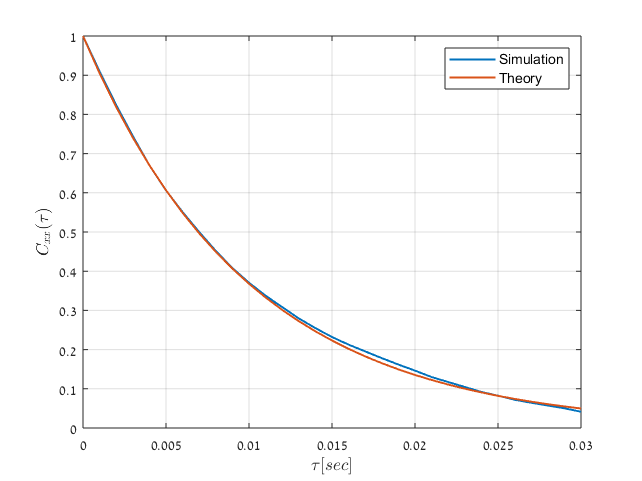

### `Example 2`

`Generate two-dimensional process`

A portion of the the process

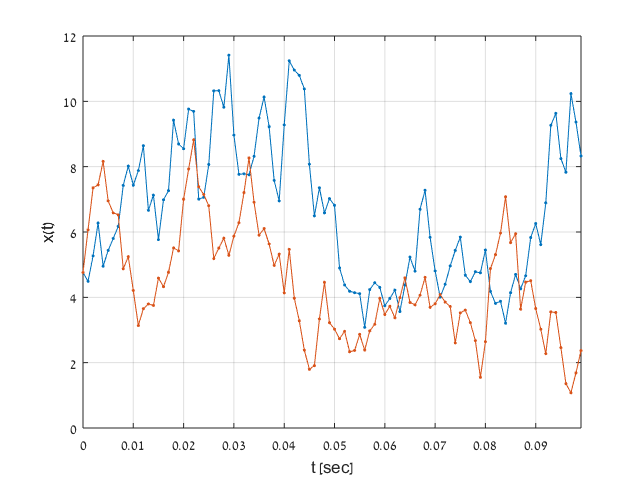

## `Reference`

D. Bykhovsky, "Simple Generation of Gamma, Gamma–Gamma, and K Distributions With Exponential Autocorrelation Function," *Journal of Lightwave Technology*, vol. 34, no. 9, pp. 2106-2110, May, 2016, [doi: 10.1109/JLT.2016.2525781](https://doi.org/10.1109/JLT.2016.2525781).

function [x,t] = process_gamma_exp(a,b,dt,tau_c,N,x0,L)

N = N-1;

if tau_c/dt < 10
    warning('For numerical accuracy reasons, it is recommended tau_c is at least 10*dt (or even higher). Otherwise, the resulting distribution may be inaccurate!')
end
switch nargin
    case 5
        L = 1;
        x = zeros(L,N+1);
        x(1) = a*b;
    case 6
        L = 1;
        x = zeros(L,N+1);
        x(:,1) = x0;
end

t = 0:dt:dt*N;

x = zeros(L,N+1);
xi = randn(L,N);
x(:,1) = a*b*ones(L,1);
for k = 1:N
    x(:,k+1) = 1/(tau_c+dt)* ...
        (x(:,k)*tau_c + a*b*dt + b*dt/2*(xi(:,k).^2-1) ...
        + sqrt(2*x(:,k)*b*tau_c*dt).*xi(:,k));
end

end